# Tutorial: Access Distributed NASA Earth Science Data from OPeNDAP Services using Matlab

*Author: ORNL DAAC*

*Date: April 10, 2018*

*Contact for *[*ORNL DAAC*](https://daac.ornl.gov/)*: *[*uso@daac.ornl.gov*](mailto:uso@daac.ornl.gov)

**Keywords: OPeNDAP, THREDDS, Matlab, temperature**

## Overview

In this tutorial, we will explore how to use ORNL DAAC data from THREDDS Data Server through OPeNDAP protocol using Matlab. THREDDS is a web server that provides direct access to scientific data sets and OPeNDAP is a protocol that allows access to remote data without having to download  the data. This example uses temporal subset of mean temperature in [global 30-year monthly climatology dataset](https://daac.ornl.gov/cgi-bin/dsviewer.pl?ds_id=542). The mean monthly temperature data is read and its attributes, dimensions and size are retrieved. A subset of mean temperature data in June is created and plotted.

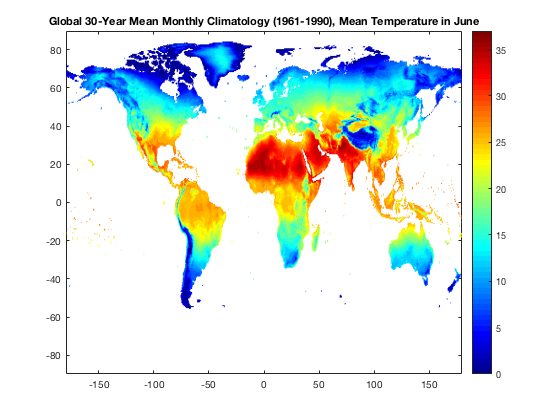

## Source Data

Spatial subsets of 30-year(1961-1990) mean monthly surface climate over  global land areas, excluding Antarctica. In this example, monthly mean temperature climatology data is obtained from [this ORNL DAAC's THREDDS server.](https://thredds.daac.ornl.gov/thredds/catalog/ornldaac/542/catalog.html?dataset=542/climate6190_TMP.nc4)  Get its OPeNDAP Data URL (https://thredds.daac.ornl.gov/thredds/dodsC/ornldaac/542/climate6190_TMP.nc4) from the OPeNDAP Dataset Access Form.   

## Prerequisites:

Matlab R2012a or later

## Procedure:

**1. Retrieve data file and all metadata**

% Define data access URL
url='https://thredds.daac.ornl.gov/thredds/dodsC/ornldaac/542/climate6190_TMP.nc4';
% Retrieve all the metadata including the groups, dimensions, variable definitions and all attributes in the NetCDF file
ncdisp(url);

Source:
           https://thredds.daac.ornl.gov/thredds/dodsC/ornldaac/542/climate6190_TMP.nc4
Format:
           classic
Global Attributes:
           Conventions = 'CF-1.0'
           history     = 'version 1.0, created on 11/05/2007-10:50'
           institution = 'Oak Ridge National Laboratory Distributed Active Archive Center (ORNL DAAC)'
           comment     = 'A dataset of mean monthly surface climate over global land areas, excluding Antarctica. Interpolated from station data to 0.5 degree lat/lon for a range of variables'
           title       = 'CRU05 0.5 Degree 1961-1990 Mean Monthly Climatology (New et al.): Mean Temperature'
           references  = 'New, M., M. Hulme, and P.D. Jones. 2000. Global 30-Year Mean Monthly Climatology, 1961-1990 (New et al.). ORNL DAAC, Oak Ridge, Tennessee, USA. http://dx.doi.org/10.3334/ORNLDAAC/542'
Dimensions:
           lat  = 360
           lon  = 720
           nv   = 2
           time = 12
Variables:
    lat               
         

**2. Read data and information from **`TMP`** variable**

% Read data from TMP variable
tmpData  = ncread(url,'TMP');
% Display information about the tmpData output
whos tmpData;

  Name           Size                   Bytes  Class     Attributes

  tmpData      720x360x12            24883200  double              



% Read the attribute associated with TMP variable
tmpDesc  = ncreadatt(url,'TMP','_FillValue');
tmpDesc

tmpDesc = int16
-9999

**3. Subset **`TMP`** variable along **`time`** dimension**

% Read and display data from time variable
timeData = ncread(url,'time');
timeData

timeData = 12×1 int32 column vector
   0
   1
   2
   3
   4
   5
   6
   7
   8
   9


% TMP variable is three-dimensional 720(longitude)x360(latitude)x12(time), We set the start index of time as 6 to subset the data in June 
start = [1 1 6];
% Set count of latitude and longitude as Inf to reads data until the end of these two dimensions.
count = [Inf Inf 1];
% Subset mean temperature data in June
subsetdata = ncread(url,'TMP',start,count); 

4. Plot your data

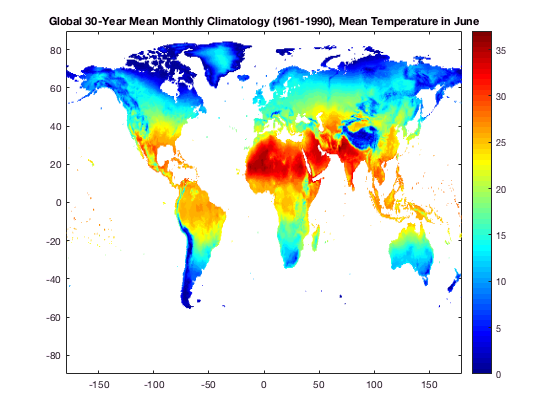

% create Y vector
Y = ncread(url,'lat');
% create X vector
X = ncread(url,'lon');
% convert data matrix in [Y x X]
C=transpose(subsetdata);
% Draws a pseudo color plot of mean temperature
pcolor(X, Y, C);
colormap(jet);
shading flat;
colorbar;
title('Global 30-Year Mean Monthly Climatology (1961-1990), Mean Temperature in June');